# Class 16/09

%Example: écrire le script testscript.m

clc;clear; close all;

% Ce script trouve les valeurs negatives d'une matrice "a"

x = [-1.2 0 3.1 6.2 -3.3 -2.1];
y = find(x<0);
z = x(y)

z =    -1.2000   -3.3000   -2.1000


### 3.2 Fonctions

Ouvrir l'editeur et enregistrer le fichier .m

- Le nom du fichier doit IMPERATIVEMENT correspondre au nom de la fonction

- Le 1° mot du fichier est **function**

- Prototype **function [var S1 var S2...] = nom_fonction(var E1, var E2...)**

- var S1 var S2... = **variable sortie**

- var E1 var E2... = **variable entrée**

- Cette ligne est forcéement la 1° ligne du fichier

- On met obligatoirement un commentaire après cette 1° ligne

function[T] = trietab(M)

ans =     4.7092    0.3360    3.1960
    6.9595    0.6881    5.3086
    6.9989    6.3853    6.5445


%Cette fonction trie un tableau
T = sort(M); % Tri le tableau M
end

trietab(10*rand(3))

%exercise: ecrire une fonction qui permet de calculer sin(x) - xcos(x)

function result = sinCosDifference(x)

ans =          0    0.1517    1.0000    2.3732    3.1416    2.0697   -1.0000   -4.5946   -6.2832


%Cette fonction permet de calculer sin(x) - xcos(x)
result = sin(x) - (x .* cos(x));
end

sinCosDifference(0:pi/4:2*pi)
%exercise: ecrire une fonction permettant de calculer la distance entre 2
%points du plan au de l'espace

function distance = calcul_distance(point1, point2)
%Cette fonction calcule la distance entre 2 points (n dimension) du plan au de l'espace
distance = sqrt(sum((point1 - point2).^2));

distance = 2.8060

end

point1 = 3*rand([1 3]);
point2 = 4*rand([1 3]);
distance = calcul_distance(point1, point2)

### 3.3 Variables entrée/sortie

Si l'utilisateur ne nomme pas la variable dans laquelle il veut recueillir la sortie de la fonction, le résultat est mis dans **ans.**

- **Les variables définies à l'interieur d'une fonction sont ****locales** **à cette fonction**

Plusieurs variables de sortie permet apparâitre

function[A x M] = test(I)
%fonction test

ans =      4     6


A = 2.*I;

B =      4     6


y = 3

N = 1.4142

x = max(I(:));

B2 =      4     6


y2 = 3

M = sqrt(min(I(:)));
end

M = [2 3];
test(M)                 %retrouve uniquement la 1° variable de sortie stackée dans ans
[B, y, N] = test(M) %retrouve toute les variables de sortie stackée dans B, y et N
[B2, y2] = test(M) % é premieres variables

Il est possible de gérer dans la fonction, les instruction à executer en fonction du nombre de variables d'entrée et/ou sortie (**nargin, nargout**)

## 4 Représentation MATLAB

### 4.1 Ouverture/Fermeture

- Par ouvrir (ou activer) une figure: **figure()** ou **figure(n), **avec n le numéro de la figure

- Par fermer une figure: **close **ou **close(n)**

- Par fermer toutes les figures: **close all**

### **4.2 Command plot**

Permet de tracer un graphe 2D (**plot(x, y)**) avec x et y deux vecteur de même taille (1xN ou Nx1)

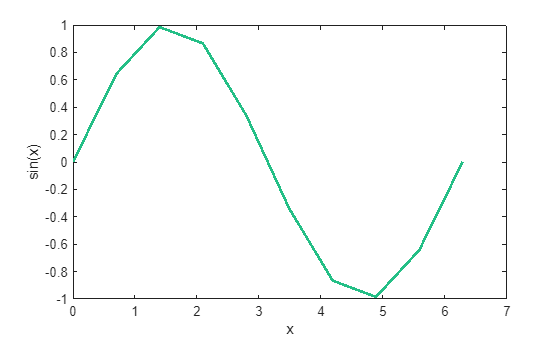

%Trace les valeurs de y en fonction de x

x1 = linspace(0, 2*pi, 10);
x2 = linspace(0, 2*pi, 100);
y1 = sin(x1);
y2 = sin(x2);

figure;
plot(x1, y1, Color="#24bf86", LineWidth=2);
xlabel('x');
ylabel('sin(x)');

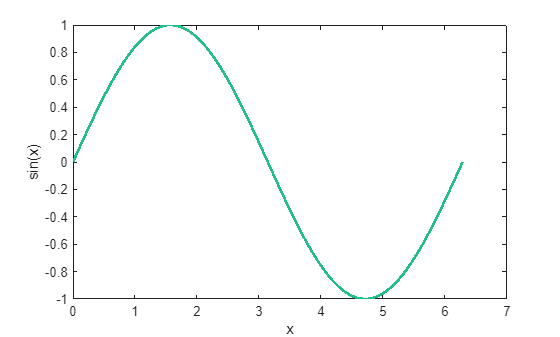

figure;
plot(x2, y2, Color="#24bf86", LineWidth=2);
xlabel('x');
ylabel('sin(x)');

Pour tracer 2 coubes sur la même figure: **hold on**

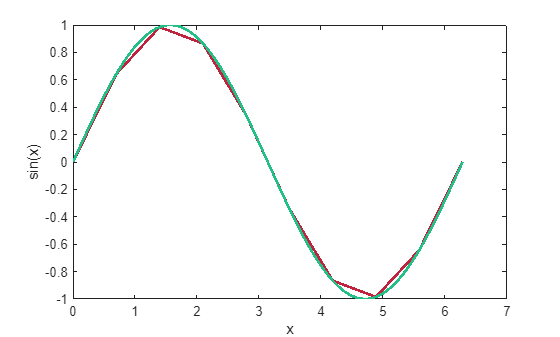

figure;
plot(x1, y1, Color="#bf243e", LineWidth=2);
xlabel('x');
ylabel('sin(x)');
hold on
plot(x2, y2, Color="#24bf86", LineWidth=2);
hold off

### 4.3 Annotations

#### 4.3.1 Grille

Pour ajouter une grille: **grid on**

#### 4.3.2 Caractéristique de la coube

**Style:**

- **"-"** trait plein (défault)

- **"- -"** pointillé

- **":"** pointillé court

- **"-."** pointillé mixte 

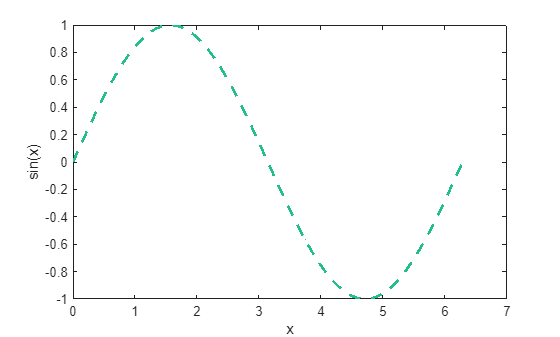

figure;
plot(x2, y2, Color="#24bf86", LineWidth=2, LineStyle="--");
xlabel('x');
ylabel('sin(x)');

**Symbole**

- **'o'**

- **'x'**

- **'*'**

- **'>'**

- **'s'**

- **'d'**

- **'p'**

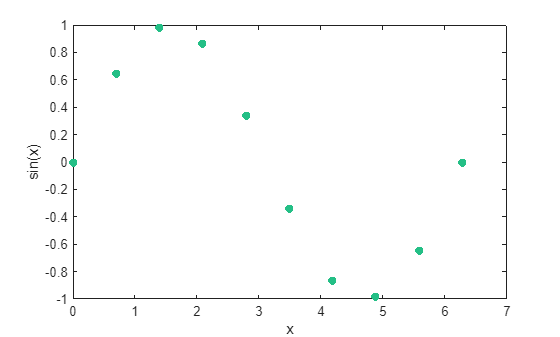

figure;
plot(x1, y1, '*', Color="#24bf86", LineWidth=2);
xlabel('x');
ylabel('sin(x)');

**Couleur**

- **'b' **bleu (défault)

- **'k' **noir

- **'y' **jaune

- **'g' **vert

- **'m' **magenta

- **'c' **cyan

- **'r'** rouge

**Vous pouvez aussi choisir la couler avec ce code HEX/RGB**

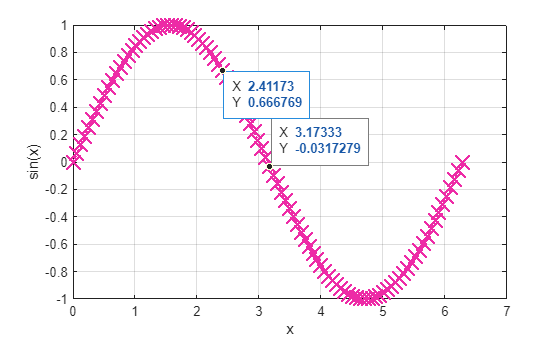

figure;
plot(x2, y2,'--x', Color= [237 43 166]/255, LineWidth=1.5, LineStyle = ":", MarkerSize = 15);
xlabel('x');
ylabel('sin(x)');

set(gca, "XGrid", "on", "YGrid", "on")

ax = gca;
chart = ax.Children(1);
datatip(chart,3.173,-0.03173);